% الف ب جیم
clc ; close all ; clear ;
syms Vo Vi;
f1(Vo, Vi) = 0.5*exp((Vi - 2*Vo)/0.025)-0.5*Vo-0.5;
j_x = diff(f1, Vo);
j_u = diff(f1, Vi);
V_OP = (Vi - 0.025)/2;
kx=j_x(V_OP,Vi);
ku=j_u(V_OP,Vi);
A = zeros(1,1);
B = zeros(1,1);
A(1,1) = kx;
B(1,1) = ku;
C = 1;
D = 0;
A

A = -109.2313

B

B = 54.3656

C

C = 1

D

D = 0

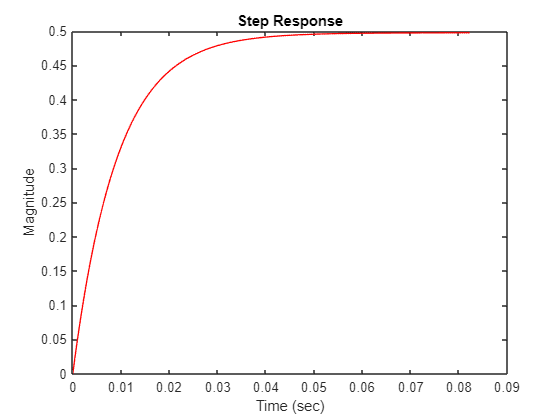

sys=ss(A,B,C,D);
[StepRes , t_step] = step(sys);
figure
plot(t_step, StepRes, 'LineWidth', 1, 'Color', 'red');
title('Step Response')
xlabel('Time (sec)')
ylabel('Magnitude')

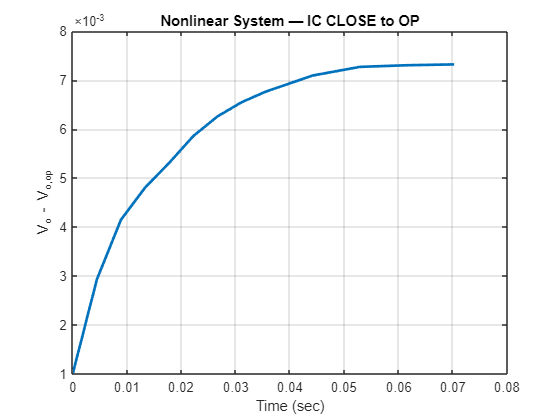

% ه
clear; close all; clc;

%% Operating point
Vi0   = 1;          % nominal input
Ampstep = 0.2;        % step amplitude
timestep = 0.1;        % step time

Vo_op = (Vi0 - 0.025)/2;   % operating point Vo

%% Two initial conditions
Vo0_close = Vo_op + 0.001;   % very close
Vo0_far   = Vo_op + 0.5;    % far from operating point

%% Time span
tspan = [0 1.5];

%% Input
Vi_fun = @(t) Vi0 + Ampstep*(t >= timestep);

%% Nonlinear ODE (CORRECT version)
ode_nonlin = @(t,Vo) 0.5*exp((Vi_fun(t)-2*Vo)/0.025) - 0.5*Vo - 0.5;

%% Solve for close initial point
[t_close, Vo_close] = ode45(ode_nonlin, tspan, Vo0_close);

%% Solve for far initial point
[t_far, Vo_far] = ode45(ode_nonlin, tspan, Vo0_far);

%% Plot 1 
figure
plot(t_close, (Vo_close-Vo_op), 'LineWidth', 2);
grid on;
xlabel('Time (sec)');
ylabel('V_o - V_{o,op}');
title('Nonlinear System — IC CLOSE to OP');

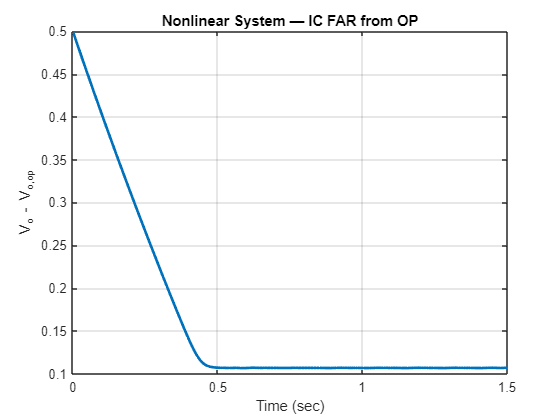


%% Plot 2 
figure
plot(t_far, (Vo_far-Vo_op), 'LineWidth', 2);
grid on;
xlabel('Time (sec)');
ylabel('V_o - V_{o,op}');
title('Nonlinear System — IC FAR from OP');